clear all
close all
syms x1 x2
f = x1-(4*(x1+x2).*exp(-x1.^2 - x2.^2)+0.1)^2

$$f = x_{1}-{\left({\mathrm{e}}^{-{x_{1}}^{2}-{x_{2}}^{2}}\,\left(4\,x_{1}+4\,x_{2}\right)+\frac{1}{10}\right)}^{2}$$

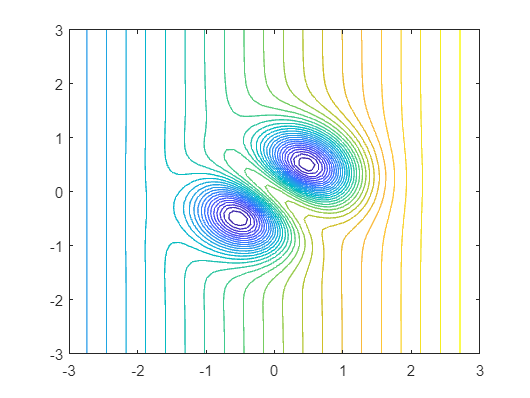

f_num = matlabFunction(f);

figure;
[X, Y] = meshgrid(-3:0.1:3, -3:0.1:3);
Z = f_num(X, Y);
contour(X, Y, Z, 30);


P01=[1, 0.5];
P02=[-1.8, -1.5];
eps = 1e-3;
Nmax = 1000;

[x, i] = max_fall(f, P01, eps, Nmax)

x =     0.4700    0.5092


i = 7

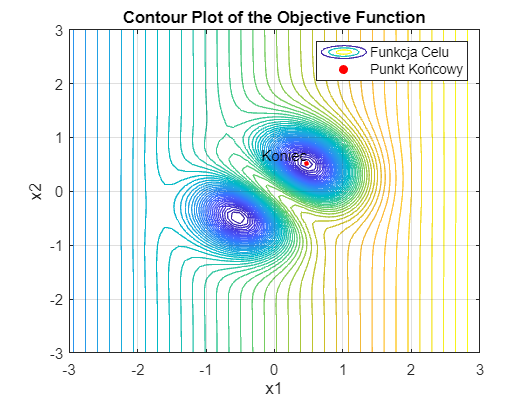

plot_result(f_num, x)

[x, i] = newton_fall(f, P01, eps, Nmax)

x =     0.4700    0.5092


i = 7

plot_result(f_num, x)

function [x, i] = max_fall(f, x0, eps, Nmax)
i = 1;
x = x0;
x_prev = x0;
syms x1 x2
grad = gradient(f, [x1, x2]).';
f_num = matlabFunction(f);

while i <= Nmax
    x_prev = x;
    d = -double(subs(grad, [x1, x2], [x(1), x(2)]));
    f_l = @(h) f_num(x(1) + h*d(1), x(2) + h*d(2));
    h = fminsearch(f_l, 0);
    x = x_prev + h*d;
    i = i + 1;
    if rms(x_prev - x) <= eps
        x = x_prev;
        return;
    end %if
end %while
end %function

function [x, i] = newton_fall(f, x0, eps, Nmax)
i = 1;
x = x0;
x_prev = x0;
syms x1 x2
grad = gradient(f, [x1, x2]).';
hesjan = hessian(f, [x1, x2]);
f_num = matlabFunction(f);

while i <= Nmax
    x_prev = x;
    d = -double(subs(grad, [x1, x2], [x(1), x(2)]));
    f_l = @(h) f_num(x(1) + h*d(1), x(2) + h*d(2));
    h = fminsearch(f_l, 0);
    x = x_prev + h*d;
    i = i + 1;
    if rms(x_prev - x) <= eps
        x = x_prev;
        return;
    end %if
end %while
end %function

function [] = plot_result(f, x)
figure;
[X, Y] = meshgrid(-3:0.1:3, -3:0.1:3);
Z = f(X, Y);
contour(X, Y, Z, 50);
title('Contour Plot of the Objective Function');
xlabel('x1');
ylabel('x2');
hold on;

% Oznacz punkt końcowy na wykresie konturów
scatter(x(1), x(2), 10, 'r', 'filled');
text(x(1), x(2), '  Koniec', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');

legend('Funkcja Celu', 'Punkt Końcowy');
grid on;
hold off;

end